### Auxilliary functions for better display :

- scale - takes the numbered samples and returns the time/frequency domain axis : $1\ldotp \ldotp \ldotp N\to 0\ldotp \ldotp \ldotp T$

- map - chooses the relative time stamp inside the new axis : $t_n \to \textrm{idx}\left(t_n \right)$

clc ; clear ;

scale = @(N,T_s) (1:N).*(T_s/N);

map = @(y,x) floor(y * length(x)/x(end));

### Part 1 : Anti-aliasing

We are asked to create a square signal and sample it with the following characteristics:

- sample time - 1 sec

- sample rate - 3200khz

- signal base frequency - 250hz

- signal amplitude - based on equipment accuracy range = 700mv

We reconstruct the signal for 2 cases :

- reconstruct the signal as it is 

- applying anti-aliasing filter before reconstructing

Here are the results :

% Load variables
square_NO_filter_250hz_3200hz_1sec = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part1\square_NO_filter_250hz_3200hz_1sec.mat");
square_without_anti_aliasing = square_NO_filter_250hz_3200hz_1sec.signal;
clear square_NO_filter_250hz_3200hz_1sec;

% Display results
square_without_anti_aliasing

square_without_anti_aliasing =    -0.7437   -0.7275   -0.7115   -0.6884   -0.6744   -0.6595    0.7199    0.7014    0.6900    0.6724    0.6532    0.6184   -0.7564   -0.7441   -0.7128   -0.7014   -0.6865   -0.6709    0.8656    0.7154    0.6971    0.6845    0.6617    0.6474    0.6292   -0.7584   -0.7437   -0.7184   -0.7057   -0.6637   -0.6676    0.7105    0.7092    0.6919    0.6750    0.6627    0.6412    0.6236   -0.7509   -0.7340   -0.7193   -0.7008   -0.6829   -0.6712    0.7245    0.7251    0.6949    0.6727    0.6623    0.6461


#### Signal without anti-aliasing filter (time domain):

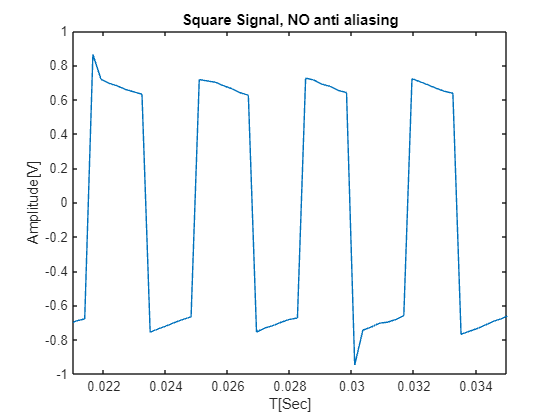

N_without = length(square_without_anti_aliasing);
Ts_without = 1;
T = linspace(0,Ts_without,N_without);


figure;
plot(T,square_without_anti_aliasing);

title("Square Signal, NO anti aliasing")

xlabel("T[Sec]")
ylabel("Amplitude[V]")
xlim([0.021,0.035])

#### Signal without anti-aliasing filter (frequency domain):

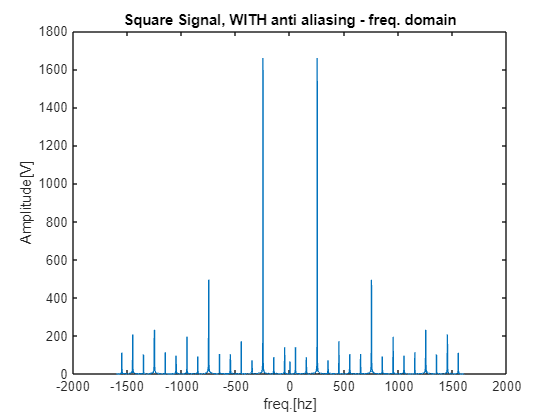

square_without_anti_aliasing_freq = fft(square_without_anti_aliasing) ;
fs_without = 3200 ;

f_without = linspace(-fs_without/2,fs_without/2,N_without);

figure;
plot(f_without,abs(fftshift(square_without_anti_aliasing_freq)));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

% Load variables
square_WITH_filter_250hz_3200hz_1sec = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part1\square_WITH_filter_250hz_3200hz_1sec.mat");
square_with_anti_aliasing = square_WITH_filter_250hz_3200hz_1sec.signal;
clear square_WITH_filter_250hz_3200hz_1sec;

% Display results
square_with_anti_aliasing

square_with_anti_aliasing =     0.6900    0.6555    0.6324   -0.1430   -0.9464   -0.6416   -0.7580   -0.6738   -0.6930   -0.3850    0.8263    0.6643    0.6988    0.6578    0.6526    0.5843   -0.4380   -0.8725   -0.6608   -0.7411   -0.6757   -0.6858   -0.1599    0.9102    0.6103    0.7238    0.6399    0.6594    0.5062   -0.6868   -0.7863   -0.6975   -0.7210   -0.6832   -0.6670    0.1410    0.9086    0.6100    0.7251    0.6409    0.6594    0.3433   -0.8602   -0.7014   -0.7271   -0.6933   -0.6855   -0.6061    0.4262    0.8324


#### Signal WITH anti-aliasing filter:

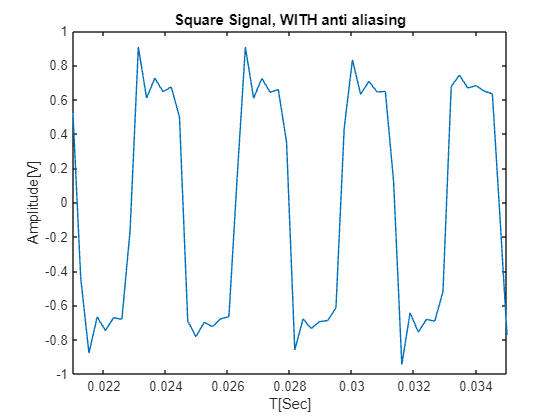

N_with = length(square_with_anti_aliasing);
Ts_with = 1;
T = linspace(0,Ts_with,N_with);


figure;
plot(T,square_with_anti_aliasing);

title("Square Signal, WITH anti aliasing")

xlabel("T[Sec]")
ylabel("Amplitude[V]")
xlim([0.021,0.035])

#### Signal WITH anti-aliasing filter (frequency domain):

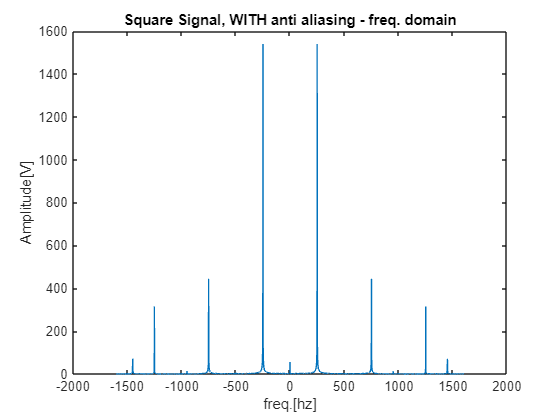

square_with_anti_aliasing_freq = fft(square_with_anti_aliasing) ;
fs_with = 3200 ;

f_with = linspace(-fs_with/2,fs_with/2,N_with);

figure;
plot(f_with,abs(fftshift(square_with_anti_aliasing_freq)));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

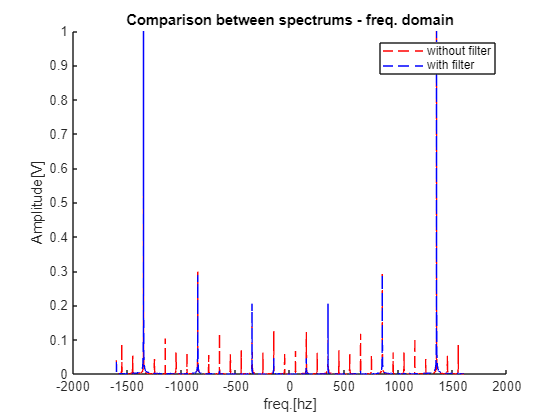

figure ; 
hold on ;

plot(f_without,abs(square_without_anti_aliasing_freq)/max(abs(square_without_anti_aliasing_freq)), "--r");
plot(f_with,abs(square_with_anti_aliasing_freq)/max(abs(square_with_anti_aliasing_freq)), "--b");

title("Comparison between spectrums - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

legend("without filter","with filter")

hold off ;

#### Zero - Padd original signal

padding_without = N_without * 2 ;

square_without_anti_aliasing_freq_padded = [zeros(1,padding_without - floor( padding_without/2)),square_without_anti_aliasing_freq,zeros(1,floor(padding_without/2))] ;

N_without_padd = N_without + padding_without ;

square_without_anti_aliasing_padded = real(ifft(square_without_anti_aliasing_freq_padded) );

T_without_padded = linspace(0,2,N_without_padd);

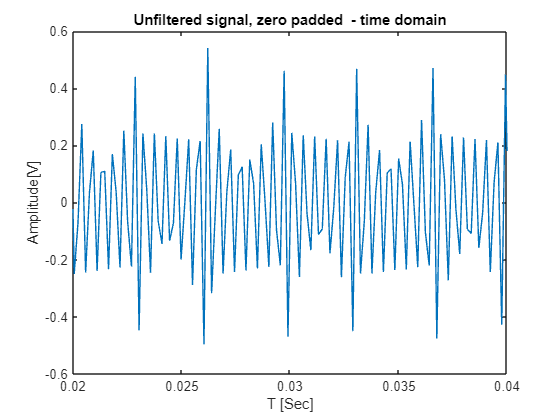

figure ;

plot(T_without_padded,square_without_anti_aliasing_padded);
xlim([0.02,0.04])

title("Unfiltered signal, zero padded  - time domain")

xlabel("T [Sec]")
ylabel("Amplitude[V]")

#### Zero - Padd anti-aliased signal

padding_with = N_with * 1 ;

square_with_anti_aliasing_freq_padded = [zeros(1,padding_with - floor( padding_with/2)),square_with_anti_aliasing_freq,zeros(1,floor(padding_with/2))] ;

N_with_padd = N_with + padding_with ;

square_with_anti_aliasing_padded = real(ifft(square_with_anti_aliasing_freq_padded));

T_with_padded = linspace(0,2,N_with_padd);

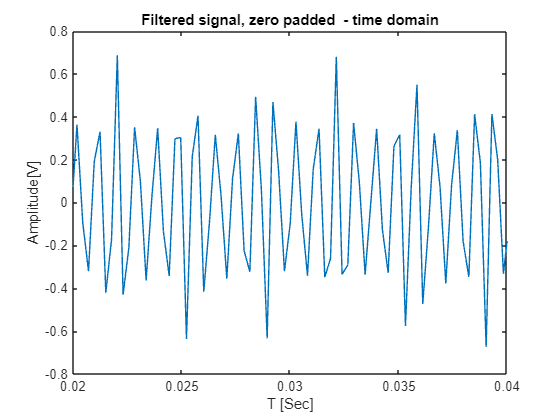

plot(T_with_padded,square_with_anti_aliasing_padded);
xlim([0.02,0.04])

title("Filtered signal, zero padded  - time domain")

xlabel("T [Sec]")
ylabel("Amplitude[V]")

### Part 2 : Quantization

% Load variables
triangular_250hz_7537hz = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part2\triangular_250hz_7537hz.mat");
triangle = triangular_250hz_7537hz.signal;
clear triangular_250hz_7537hz;

% Display results
triangle

triangle =     0.2265    0.3280    0.4470    0.5300    0.6347    0.7323    0.7193    0.6080    0.4955    0.3852    0.2802    0.1761    0.0622   -0.0467   -0.1453   -0.2539   -0.3583   -0.4699   -0.5417   -0.6582   -0.7571   -0.7564   -0.6520   -0.5343   -0.4221   -0.3251   -0.2041   -0.1023    0.0122    0.1136    0.2054    0.3166    0.4243    0.5199    0.6152    0.7183    0.7371    0.6272    0.5169    0.4038    0.2948    0.1719    0.0766   -0.0200   -0.1378   -0.2406   -0.3372   -0.4380   -0.5414   -0.6416


#### Import and display trianglular signal 

- Sampling length : $L_0 \ge \;3000\textrm{hz}$

- base freq. : $f=250\textrm{hz}$

rest of the system characteristics are upto consideration of the student...

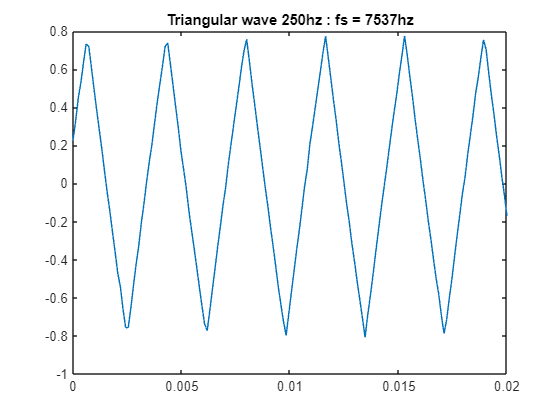

figure ;

N_tri = length(triangle);
T = linspace(0,2,N_tri);
plot(T,triangle)
title('Triangular wave 250hz : fs = 7537hz')
xlim([0,0.02])

#### Explore statistical model of the quantization error :

We want to see a uniform distribution of the quantization error along the representing bits.

- First, we want to normalize the signal since the quantizer assumes a dynamic range of [-1,1].

- Then we take the normalized signal and pass it through the quantizer.

- Finally we compare between the original signal and the quantized signal and plot the errors in a histogram.

We assume that the original 12bit accuracy holds all the information of the original signal.

We will examine the distribution of the error over the dynamic range for lower accuracies (8bit, 6bit ,etc.)

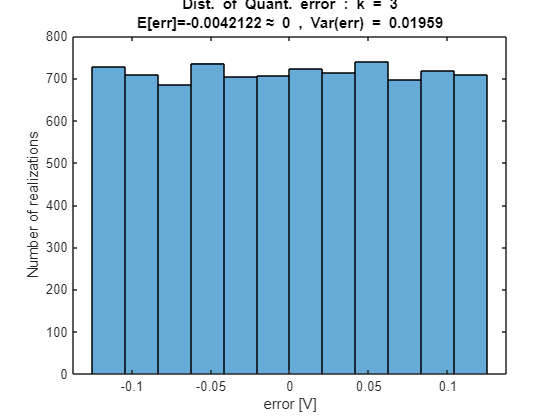

function [out]=quantize(in, R_bits, S_bits);
% Input:
% in : sampled vector.
% R_bits : Number of Bits in sampling card.
% output :
% S_bits : Number of bits in simulated sampling card.

% Checking new simulated card.
 if (R_bits<S_bits | S_bits<1),
 error(' Wrong simulated sampling card no. of bits')
 end
 
% Checking dynamic range. Max value is 2^(R_bits-1).
 M_val = max( abs(in) );
 if M_val>(2^(R_bits-1)) ,
 error('Error in sampled data range')
 end

% Changing data to new simulated sampling card.

 if (S_bits==R_bits)
 out=in;
 else 
 out = (floor( in*2^( S_bits - 1 )) + 0.5 )/( 2^( S_bits -1 ));
 end
end

X = triangle/max(abs(triangle));
Q_error = @(X,S_bits) X - quantize(X,12,S_bits);

k = 2 ;
E = Q_error(X,k);

figure ; 
Delta = 2 / 2^k ;
histogram(E,12,"BinLimits",[-Delta/2, Delta/2])
title_str1 = "Dist. of Quant. error : k = " + num2str(k);
title_str2 = "E[err]=" + num2str(mean(E)) + "\approx 0 , Var(err) = " + num2str(std(E)^2);

% title({title_str1,title_str2},"fontsize",48)
% xlabel("error [V]","fontsize",48)
% ylabel("Number of realizations","fontsize",48)

title({title_str1,title_str2})
xlabel("error [V]")
ylabel("Number of realizations")

### Part 3 :

We sample sine wave with increasing freq. while using the same sampling rate to illustrate the importance of Nyquists condition.

% 1. Open a visual folder selection dialog
% It will start in your lab3 folder, but you can navigate anywhere
default_start_path = 'C:\Users\yizharf\coding\bgu\dsp_lab\lab3\';
folder_path = uigetdir(default_start_path, 'Select the folder with your .mat files');

% 2. Safety check: stop the script if you click "Cancel"
if folder_path == 0
    disp('Folder selection canceled.');
    return; 
end

% 3. Search for all .mat files in the folder you selected
file_pattern = fullfile(folder_path, '*.mat'); 
mat_files = dir(file_pattern);


Successfully loaded: sin_250hz_fs__500hz.mat
Successfully loaded: sin_350hz_fs__500hz.mat
Successfully loaded: sin_450hz_fs__500hz.mat


% Safety check: alert you if the folder is empty
if isempty(mat_files)
    fprintf('No .mat files found in: %s\n', folder_path);
    return;
end

% 4. Initialize an empty struct to hold all the data
all_signals = struct();

% 5. Loop through each file found
for k = 1:length(mat_files)

    % Get the full path and the filename
    base_file_name = mat_files(k).name;
    full_file_name = fullfile(mat_files(k).folder, base_file_name);

    % Extract just the name without the '.mat' extension 
    [~, name_without_ext, ~] = fileparts(base_file_name);

    % Load the file contents into the struct
    all_signals.(name_without_ext) = load(full_file_name);

    % Print a confirmation message
    fprintf('Successfully loaded: %s\n', base_file_name);
end

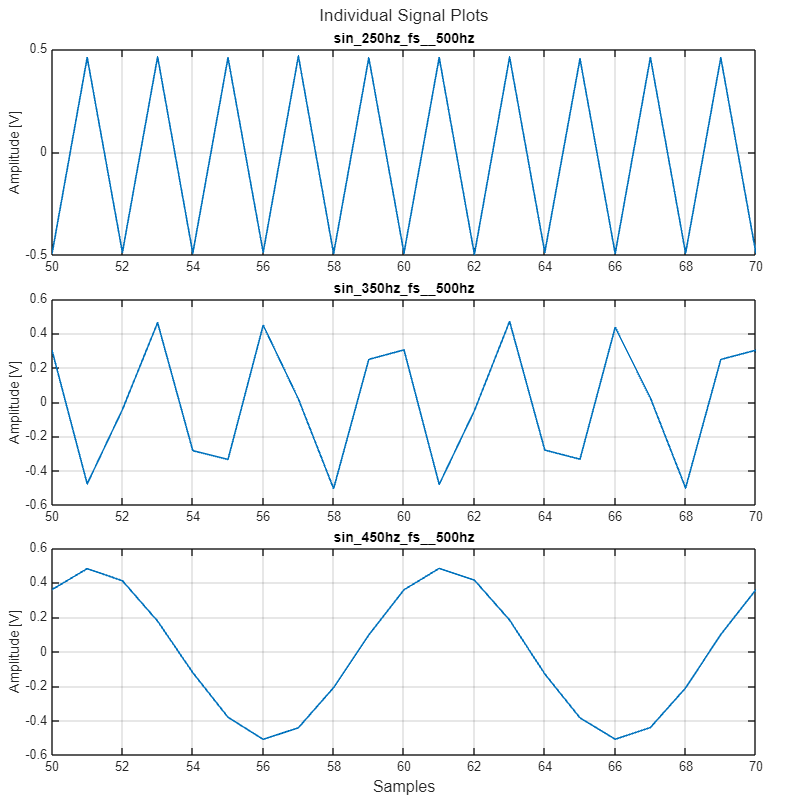


% Get the names of all the files you loaded
file_names = fieldnames(all_signals);

num_files = length(file_names);

% Create a new, slightly taller figure window
figure('Name', 'Separate Signal Plots', 'Color', 'w', 'Position', [100, 100, 800, 800]);

% Set up a tiled layout (num_files rows, 1 column)
t = tiledlayout(num_files, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Individual Signal Plots');

% Loop through each file
for i = 1:num_files
    current_file = file_names{i};

vocal_recording =     0.0021   -0.0067    0.0037   -0.0005    0.0073   -0.0028   -0.0109    0.0063   -0.0022   -0.0022    0.0066    0.0044    0.0014    0.0014   -0.0028   -0.0018   -0.0028   -0.0035   -0.0074    0.0024   -0.0002    0.0057   -0.0051   -0.0142    0.0083    0.0105   -0.0031    0.0066   -0.0015   -0.0057    0.0073    0.0014   -0.0012    0.0008    0.0004    0.0037   -0.0044   -0.0012   -0.0009   -0.0067   -0.0067   -0.0035   -0.0048    0.0014    0.0014   -0.0009    0.0128   -0.0012   -0.0194    0.0076


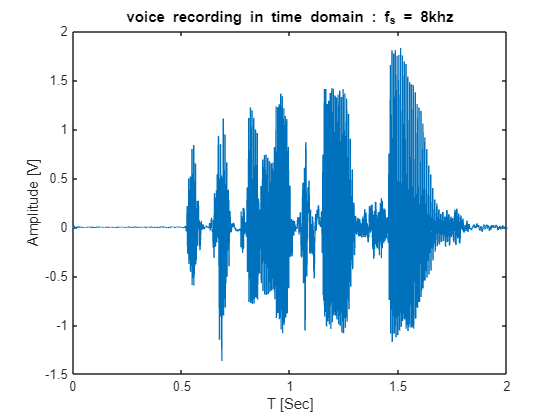

    
    % Get the contents of this specific file
    file_contents = all_signals.(current_file);
    var_names = fieldnames(file_contents);
    signal_data = file_contents.(var_names{1}); 
    
    % Move to the next "tile" (subplot)
    nexttile;
    
    % Plot the signal
    plot(signal_data, 'LineWidth', 1.2);
    
    % Format this specific tile
    % title(current_file, 'Interpreter', 'none','FontSize',48); % Uses the filename as the title
    % ylabel('Amplitude [V]','FontSize',36);

    title(current_file, 'Interpreter', 'none'); % Uses the filename as the title

    ylabel('Amplitude [V]');

    grid on;
    xlim([50,70])
end

% Add a shared X-axis label at the very bottom
xlabel(t, 'Samples');

Unrecognized function or variable 'vocal_recording'.

### Part 4 :

We are asked to record our own voice saying : "אפוקליפסה עכשיו"

- Recording time : $T_s =2\mathrm{Sec}$

- Sampling rate : We set it based on our knowledge that speech freq. stand around $f\approx 6\ldotp 4\mathrm{khz}$

- The rest is set by the system...

% Load variables
vocal_recording2 = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part4\vocal_recording.mat");
vocal_recording = vocal_recording2.signal;
clear vocal_recording2;

% Display results
vocal_recording

#### Plotting our signal in time domain

N_speech = length(vocal_recording);
T_s = 2;
T_speech = linspace(0,T_s,N_speech);

figure ;
plot(T_speech,vocal_recording)

% fontsize(36,"pixels")
% title("voice recording in time domain : f_s = 8khz","Fontsize",48)
% xlabel("T [Sec]","Fontsize",36)
% ylabel("Amplitude [V]","Fontsize",36)

title("voice recording in time domain : f_s = 8khz")
xlabel("T [Sec]")
ylabel("Amplitude [V]")

#### Play recording...

% Fs = (N_speech)/T_s ;
Fs = 8000;
% soundsc(vocal_recording,Fs)

#### Plotting our signals estimated spectrum using Welch's spectrum estimation method

pwelch(vocal_recording,[],[],[],Fs)

% title("Spectrum of original voice recording","Fontsize",48)
% xlabel("Frequency (kHz)","Fontsize",36)
% ylabel("Power/frequency (dB/Hz)","Fontsize",36)

title("Spectrum of original voice recording")
xlabel("Frequency (kHz)")
ylabel("Power/frequency (dB/Hz)")

#### Simulating sampling card with different sound resolution

We will use the quntize.m function to simulate that :

vocal_norm = vocal_recording / max(abs(vocal_recording));


bits_to_test = [12 ,8, 4, 2]; 
i = 4;

current_bits = bits_to_test(i);

vocal_quantized = quantize(vocal_norm, 16, current_bits); 

% 4. Play the crushed audio
soundsc(vocal_quantized, Fs);

N_speech = length(vocal_recording);
T_s = 2;
T_speech = linspace(0,T_s,N_speech);

figure ;
plot(T_speech,vocal_quantized)
fontsize(36,"pixels")
title("Reconst. in time domain : " + num2str(bits_to_test(i)) + "bits resolution" ,"Fontsize",48)
xlabel("T [Sec]","Fontsize",36)
ylabel("Amplitude [V]","Fontsize",36)

#### Simulating phone line :

- We sample at 6.4khz to simulate the 3.2khz freq. of phone speech

- We then quantize with 8bit resolution

% Load variables
vocal_recording_6400hz2 = load("C:\Users\yizharf\coding\bgu\dsp_lab\lab3\part4\vocal_recording_6400hz.mat");
vocal_recording_6400hz = vocal_recording_6400hz2.signal;
clear vocal_recording_6400hz2;

% Display results
vocal_recording_6400hz

vocal_6400hz_norm = vocal_recording_6400hz / max(abs(vocal_recording_6400hz));

Fs = 7000 ;

bits_to_test = 8 ;

vocal_6400_quantized = quantize(vocal_6400hz_norm, 16, bits_to_test); 

% 4. Play the crushed audio
soundsc(vocal_quantized, Fs);

N_speech = length(vocal_recording_6400hz);
T_s = 2;
T_speech = linspace(0,T_s,N_speech);

figure ;
plot(T_speech,vocal_recording_6400hz)
fontsize(36,"pixels")

% title("3.2khz signal Reconst. in time domain : 8bits resolution" ,"Fontsize",48)
% xlabel("T [Sec]","Fontsize",36)
% ylabel("Amplitude [V]","Fontsize",36)

title("3.2khz signal Reconst. in time domain : 8bits resolution")
xlabel("T [Sec]")
ylabel("Amplitude [V]")

pwelch(vocal_recording_6400hz,[],[],[],6400)
% title("Spectrum of 3.2khz voice recording","Fontsize",48)
% xlabel("Frequency (kHz)","Fontsize",36)
% ylabel("Power/frequency (dB/Hz)","Fontsize",36)
title("Spectrum of original voice recording")
xlabel("Frequency (kHz)")
ylabel("Power/frequency (dB/Hz)")


















